clc; clear all; close all hidden;
dry= imread('../Images/Dry01.jpeg')

dry = 738×1599×3 uint8 array
dry(:,:,1) =

   207   213   218   217   211   208   211   215   215   223   222   212   208   199   159   115    55    59    59   122   217   235   206   210   213   202   203   212   204   185   180   191   197   183   171   154   153   192   223   212   210   226   228   211   223   223   201   216   239   217   221   198   165   110   125   163   138   120   121   148   175   180   183   186   164   147   137   134   136   136   141   145   142   163   192   208   207   201   199   201   206   201   202   207   205   184   156   136   148   162   177   188   202   220   230   229   222   210   217   222   219   187   157   188   243   234   208   201   196   201   220   206   212   208   204   201   211   224   208   171   134   157   133   106   146   197   213   218   197   196   199   206   216   220   206   190   201   173   112    69    95   150   188   207   203   202   186   179   198   206   186   161   179   140   108   107   122   129   135   

wet = imread('../Images/Wet01.jpeg')

wet = 738×1599×3 uint8 array
wet(:,:,1) =

   171   176   183   186   176   154   126   107    90    92    95   103   117   134   152   164   176   182   191   198   210   221   226   225   220   209   201   198   196   188   184   187   181   187   187   188   196   189   170   158   132   123   122   135   145   149   157   170   180   178   175   171   167   168   173   176   178   172   176   181   176   168   165   168   216   216   217   217   214   207   197   191   170   163   167   195   229   243   229   208   165   145   127   120   123   121   124   128   133   133   136   138   132   131   144   161   158   170   193   207   206   202   201   195   174   163   150   146   151   164   176   183   177   180   184   181   182   192   210   223   223   224   228   224   219   209   201   197   200   198   199   199   202   204   205   204   195   182   161   142   129   127   131   135   142   146   156   164   174   182   186   191   191   192   189   187   188   184   176   

imshow(dry)

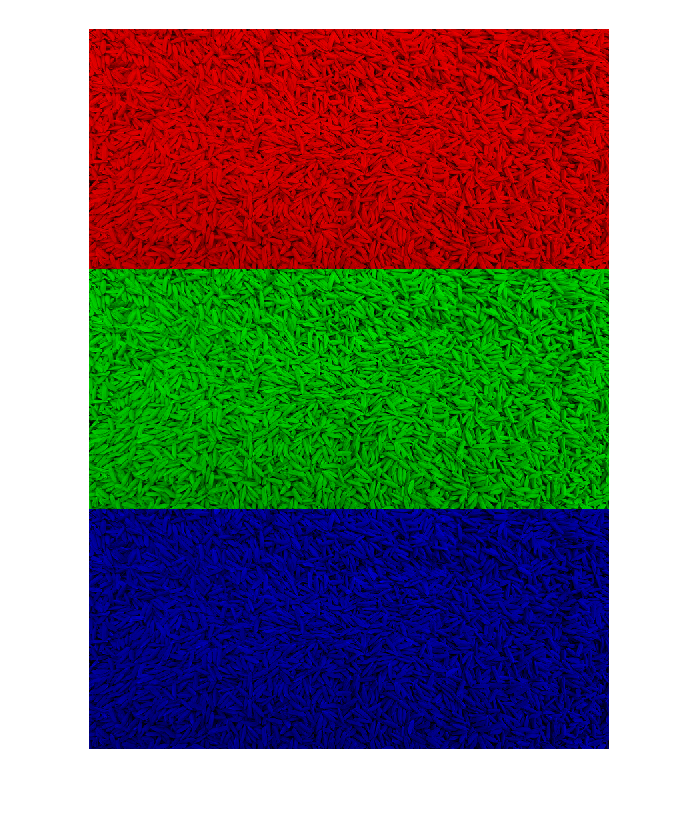

R = dry;
R(:,:,2:3) = 0;
G = dry;
G(:,:,[1 3]) = 0;
B = dry;
B(:,:,1:2) = 0;
montage({R G B},'size',[3 1]);

% R VS L 
sd = size(dry)

sd =          738        1599           3


sw = size(wet)

sw =          738        1599           3


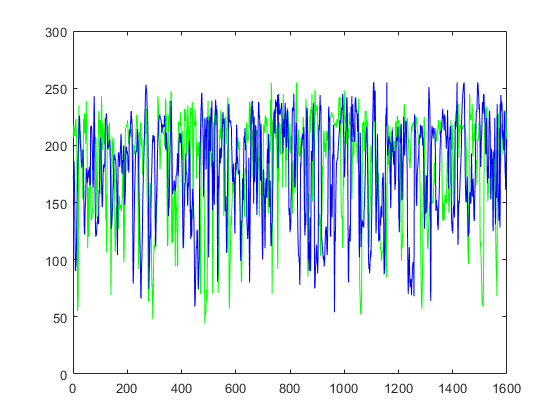

for row = 1:1

L = 1:1:sd(2);
Rd = dry(row,:,1);
Rw = wet(row,:,1);
figure()
plot(L,Rd, "Color","green")
hold on
plot(L,Rw, "Color","blue")
hold off;
end

mean_dry = [];
mean_wet = [];
k = 1;
for i = 1:50:sd(2)-9
    mean_dry(k) = mean(dry(100,i:i+9,3));
    mean_wet(k) = mean(wet(100,i:i+9,3));
    k = k+1;
end

s = size(mean_wet)

s =      1    32


L = 1:1:s(2)

L =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


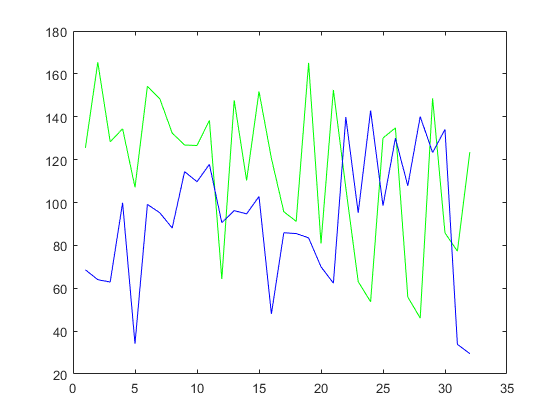

figure()
plot(L,mean_dry, "Color","green")
hold on
plot(L,mean_wet, "Color","blue")
hold off;

T = table(L',Rd',Rw');
T.Properties.VariableNames=["Length","Red-Dry","Red-wet"]

T = 1599×3 table
    Length    Red-Dry    Red-wet
    ______    _______    _______

       1        207        171  
       2        213        176  
       3        218        183  
       4        217        186  
       5        211        176  
       6        208        154  
       7        211        126  
       8        215        107  
       9        215         90  
      10        223         92  
      11        222         95  
      12        212        103  
      13        208        117  
      14        199        134  
      15        159        152  
      16        115        164  


writetable(T,'Data.csv')  